% ----- %
clc; clear all; close all;
addpath(genpath('./doc'));
addpath(genpath('./lib'));
% addpath(genpath('../'));
% addpath(genpath('path/to/ndsparse'));
addpath(genpath('/Users/benjaminsylvanus/Documents/GitHub/SparseMatrixGenerator/ndSparse_G4_2021_03_16'));

swc = swcreader();

User selected /Users/benjaminsylvanus/Desktop/NC6000_ID4138580687.swc



% Define Coordinates and Range
X = swc.tree.X; Y = swc.tree.Y; Z = swc.tree.Z;
dim = [X Y Z]; 

% Threshold Radii
[~,~,bin] = histcounts(swc.tree.Radii, 5);
avg = mean(swc.tree.Radii(bin==1));
swc.tree.Radii(swc.tree.Radii < avg)=avg;
r = swc.tree.Radii;
ranges = [min(dim - r); max(dim+r)]; % (min - ri) (max + ri)

% Define Voxel Size
VSIZE = avg;

% Translate X,Y,Z
tran = ((dim-ranges(1,:))./VSIZE)+1;

% Update Bounds
boundSize=ceil((ranges(2,:) - ranges(1,:))./VSIZE)+4;

% Radii Scale
R = swc.tree.Radii./(VSIZE);

% Set Tree XYZ to Translated
swc.tree.X = tran(:,1);
swc.tree.Y = tran(:,2);
swc.tree.Z = tran(:,3);

swc.tree.Radii = R;

% Define Bounds for pairing based on Voxel Size
b = calcBounds(swc,VSIZE);

% Create Sparse
A=ndSparse.build(boundSize);

%% batch initialization
tic;

XD = swc.tree.X - swc.tree.X';
YD = swc.tree.Y - swc.tree.Y';
ZD = swc.tree.Z - swc.tree.Z';

toc;

Elapsed time is 0.198169 seconds.



tic;

xds = XD.^2;
yds = YD.^2;
zds = ZD.^2;

dists = sqrt(xds + yds + zds);

toc;

Elapsed time is 0.374609 seconds.



dist_id = dists < 50;
full = [];
batch = struct();
c = 1;
i = 1;
while true
    temp = swc.tree(dist_id(:,i),:);
    a = ~ismember(temp.NodeId,full);
    full = [full; temp.NodeId(a)];
    rsd = swc.tree.NodeId(~ismember(swc.tree.NodeId,full));
    batch.Elements(c,1) = {temp.NodeId(a)};
    c=c+1;
    if numel(rsd>0)
        i = rsd(1);
    else
        break;
    end
end

% batch bound
for i = 1:numel(batch.Elements)
    miX = 100000; miY = 100000; miZ = 100000;
    mxX = -1000; mxY = -1000; mxZ = -1000;
    ele = batch.Elements{i,1};
    comb = [miX miY miZ; mxX mxY mxZ];
    for j = 1:numel(batch.Elements{i,1})
        Bound = b.a{ele(j),1};
        Sx = Bound(1,1); Sy = Bound(1,2); Sz = Bound(1,3);
        Nx = Bound(2,1); Ny = Bound(2,2); Nz = Bound(2,3);
        small = find(Bound(1,:) < comb(1,:));
        large = find(Bound(2,:) > comb(2,:));

        comb(1,small) = Bound(1,small);
        comb(2,large) = Bound(2,large);
    end
    batch.Bound(i,1) = {comb};
    batch.SIZE(i) = numel(ele);
end

MAIN LOOP

clf;
% Element Count 
el__Count = numel(batch.Elements);
limit =276

limit = 276

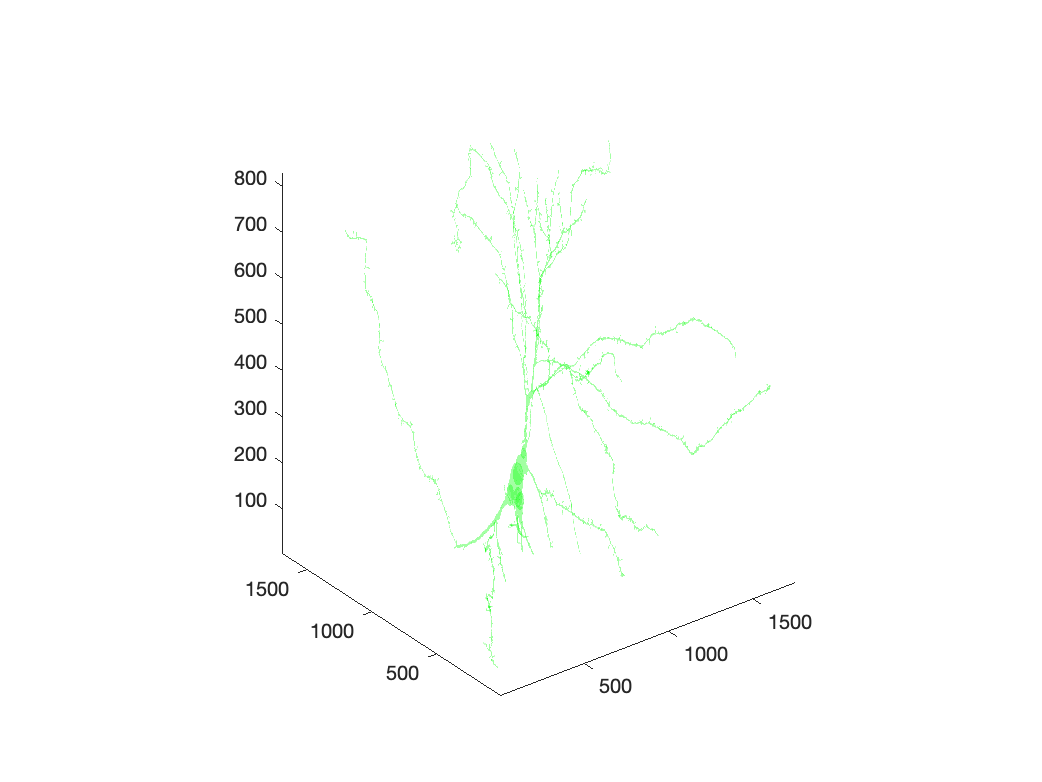

%% Batch Loop 
clf;
A=ndSparse.build(boundSize);

ecount = 0; prevElapse = 0; tic;

for i = 1:limit
        Bound = batch.Bound{i,1};

        Sx = Bound(1,1) - 1;
        Sy = Bound(1,2) - 1;
        Sz = Bound(1,3) - 1;

        Nx = Bound(2,1) + 1;
        Ny = Bound(2,2) + 1;
        Nz = Bound(2,3) + 1;

        [y0,x0,z0]=meshgrid(Sy:Ny,Sx:Nx,Sz:Nz);

        pos_fill = ndSparse.build(range(Bound)+3);

        for j = 1:batch.SIZE(i)

            element = batch.Elements{i,1}(j);

            p1 = swc.tree{element,2:5}; 

            pair = swc.pairElement(element);

            p2 = pair{1,2:5};

            x1 = p1(1); y1 = p1(2); z1 = p1(3); r1 = p1(4);

            x2 = p2(1); y2 = p2(2); z2 = p2(3); r2 = p2(4);

            pos = swc2v(x0,y0,z0,x1,x2,y1,y2, ...
                        z1,z2,r1,r2,Nx,Ny,Nz);

            pos_fill = pos_fill | pos;

        end

        batch.TF(i) = {pos_fill};

%         %{ 

%       comment out to if when running full cell 

        hold on;
        is = isosurface(pos_fill,0);
        is.vertices = is.vertices + [Sy Sx Sz];
        p = patch('Faces',is.faces,'Vertices',is.vertices);
        p.FaceColor='green';
        p.FaceAlpha=0.2;
        p.EdgeColor='none';
        view(3);
        axis tight;
        daspect([1,1,.4]);
        p.Clipping = 'off';
        pause(0.5);

%         %}

        ecount = ecount + batch.SIZE(i); 

        A(Sx:Nx,Sy:Ny,Sz:Nz) = pos_fill;

        telapse = toc;

        rate = batch.SIZE(i)/(telapse-prevElapse);

        prevElapse=telapse;

%         s1 = sprintf(['I: %d \t Time: %f \t' ...
%             ' Elements: %d \t Rate: %f \n'], ...
                    ...
%                     i,telapse, ecount,rate);
%         disp(s1);
%         clc;

end

Functions

% Replaced Calulation for r comparison

function pos = swc2v(x0,y0,z0,x1,x2,y1,y2,z1,z2,r1,r2,Nx,Ny,Nz)
    t = ( (x0-x1)*(x2-x1) + (y0-y1)*(y2-y1) + (z0-z1)*(z2-z1) ) ./...
        ((x2-x1)^2 + (y2-y1)^2 + (z2-z1)^2);
    x = x1 + (x2-x1)*t;
    y = y1 + (y2-y1)*t;
    z = z1 + (z2-z1)*t;

    list1 = (x-x1).*(x-x2) + (y-y1).*(y-y2) + (z-z1).*(z-z2) <0;
    list2 = ~list1;
    
    dist2 = (x0-x).^2 + (y0-y).^2 + (z0-z).^2;


%     r = r1 + sqrt((x-x1).^2 + (y-y1).^2 + (z-z1).^2) /...
%         sqrt((x2-x1)^2+(y2-y1)^2+(z2-z1)^2) * (r2-r1);

%     r = ( c + r2 ) / (sqrt ( 1 - ( |r1-r2 | / l ) )

%     c = ( |r1 - r2| * l ) / L

    if r2 > r1 
        pos = swc2v(x0,y0,z0,x2,x1,y2,y1,z2,z1,r2,r1,Nx,Ny,Nz);
    else


    rd = abs( r1 - r2 );

    % distance from orthogonal vector to p2  
    l = sqrt( (x-x2).^2 + (y-y2).^2 + (z-z2).^2 );

    % distance from p1->p2     
    L = sqrt((x2 - x1) ^ 2 + (y2 - y1) ^ 2 + (z2 - z1) ^ 2);

    c = (rd * l) ./ sqrt((x2 - x1) ^ 2 + (y2 - y1) ^ 2 + (z2 - z1) ^ 2);
    r = (c + r2) ./ sqrt(1 - ( (rd / L) .^2) );


    pos1 = dist2<=(r.^2); % smaller in one line and less than and equal
    pos2 = ( ( (x0-x1).^2 + (y0-y1).^2 + (z0-z1).^2 ) <= (r1^2) ) | ...
           ( ( (x0-x2).^2 + (y0-y2).^2 + (z0-z2).^2 ) <= (r2^2) );
    pos = zeros(size(x0)); % use false

    
    pos(list1) = pos1(list1);
    pos(list2) = pos2(list2);
    end
end

% Input [r1;r2] [x1 y1 z1; x2 y2 z2]
% Output [min(ri-ci) max(ri-ci)]
function b = calcBounds(swc,vs)    
    b = struct();
    t = swc.tree;
    mr = vs;
    for i = 1:numel(t.X)
        pair = swc.pairElement(i);
        b.a(i,:) =  pairBounds(t(i,:),pair,vs);         
    end

end

function b = pairBounds(p1, p2, m)
    % ri: pair radii
    % pxi: pair coords
    ri = [p1.Radii; p2.Radii]; 
    pxi = [p1{1,2:4}; p2{1,2:4}];
    b = {[round(min(pxi-ri)) + 1; ceil(max(pxi+ri)) + 1]};
    ba = [min(pi-(ri+m)), max(pi+(ri+m))];

end

function h = bbox(b,ba,pi)
    o = [b(1,1) b(1,2) b(1,3)];
    edgeLength = [b(1,4) b(1,5) b(1,6)]-o;
    hold on;
    c1 = rand;
    c2 = rand;
    plotcube(edgeLength,o,.01,[1 c2 0]);
    o = [ba(1,1) ba(1,2) ba(1,3)];
    edgeLength = [ba(1,4) ba(1,5) ba(1,6)]-o;
    plotcube(edgeLength,o,.01,[c1 c2 0]);
    plot3(pi(:,1),pi(:,2),pi(:,3));
end

function [NodeID, Coords, Radii, Parents] = openswc(pathname,filename, A)
    swc = [];
    for counter  = 1 : length (A)
        if ~isempty (A{counter})  % allow empty lines in between
            % allow comments: lines starting with #:
            if ~strcmp (A{counter} (1), '#')
                swc0   = textscan (A{counter}, '%f')';
                swc    = [swc; swc0{1}'];
            end
        end
    end
    
    NodeID = swc(:,1); Coords = swc(:,3:5);
    Radii = swc(:,6); Parents = swc(:,7);
end